# Example 6.13: Fourier Transform of a Pulse and of a Gaussian Signal

Note: this script reproduces Example 6.13 (Section 6.3.2) of **Statistics for Chemical Engineers**: frequency content of a pulse and of Gaussians with different widths. Victor Z UW-Madison, 2020 illustrate fourier transform of different filters

clc;  clear all; close all hidden; format short 

L = 1000;                                 % length of signal
Fs= 100;                                  % Hz (sampling frequency)
T = 1/Fs;                                 % sec (sampling period)
t = (0:L-1)*T;                            % time vector
om = Fs*(0:(L/2))/L;                      % frequency vector

## Pulse

check moving average

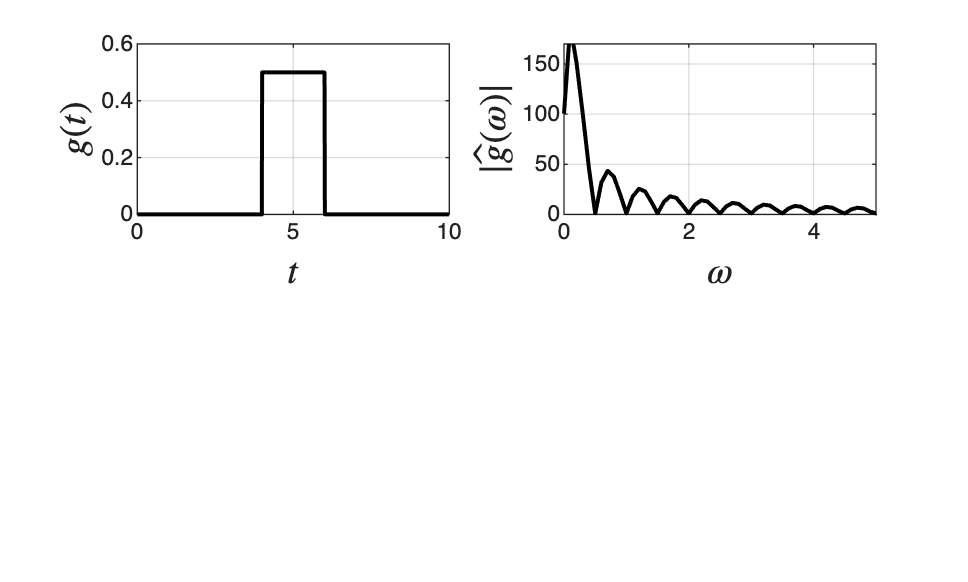

f=unifpdf(t,4,6);

fh = fft(f);                              % compute DFT 
m = abs(fh);                              % magnitude
mf = m(1:L/2+1);                          % eliminate symmetry
mf(2:end-1) = 2*mf(2:end-1);

% visualize signal in time and frequency domain
figure(1)
subplot(2,2,1)
plot(t,f,'black','LineWidth',1.5)
grid on
ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

figure(1)
subplot(2,2,2)
plot(om,mf,'black','LineWidth',1.5)
grid on
ylabel('$|\hat{g}(\omega)|$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)
axis([0 5 0 170])

## Gaussian signals

get signal

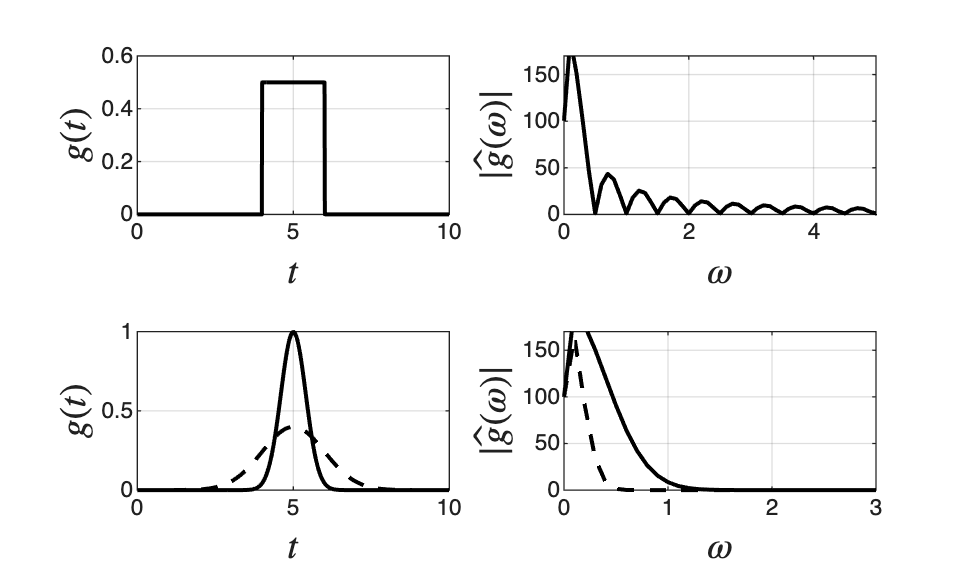

f=normpdf(t,5,0.4);

fh = fft(f);                              % compute DFT 
m = abs(fh);                              % magnitude
mf = m(1:L/2+1);                          % eliminate symmetry
mf(2:end-1) = 2*mf(2:end-1);

% visualize signal in time and frequency domain
figure(1)
subplot(2,2,3)
plot(t,f,'black','LineWidth',1.5)
grid on
hold on
ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

figure(1)
subplot(2,2,4)
plot(om,mf,'black','LineWidth',1.5)
grid on
hold on
ylabel('$|\hat{g}(\omega)|$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)
axis([0 3 0 max(mf)])

% get signal
f=normpdf(t,5,1);

fh = fft(f);                              % compute DFT 
m = abs(fh);                              % magnitude
mf = m(1:L/2+1);                          % eliminate symmetry
mf(2:end-1) = 2*mf(2:end-1);

% visualize signal in time and frequency domain
figure(1)
subplot(2,2,3)
plot(t,f,'black--','LineWidth',1.5)
grid on
ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

figure(1)
subplot(2,2,4)
plot(om,mf,'black--','LineWidth',1.5)
grid on
ylabel('$|\hat{g}(\omega)|$','Interpreter','Latex','FontSize',14)
xlabel('$\omega$','Interpreter','Latex','FontSize',14)
axis([0 3 0 170])
print -depsc ch6_fourier_filters.eps

## Note

As in the book, a wide Gaussian has only low frequencies and a narrow one needs high frequencies: sigma controls the frequency content of the filter.